clear all;
close all;

Implicit Euler Method

Delta_t=1.0;
t=0:Delta_t:10.0;
 
x(1)=1.0;
 
for n=1:length(t)-1
    x(n+1)=Findxnplus1(Delta_t,x(n));
end

figure
plot(t,x,'ko-','linewidth',2,'Markersize',10)
hold on
 
tplot=0:0.01:10.0;
truesolution=@(t)(1./(t+1))

truesolution = function_handle with value:
    @(t)(1./(t+1))


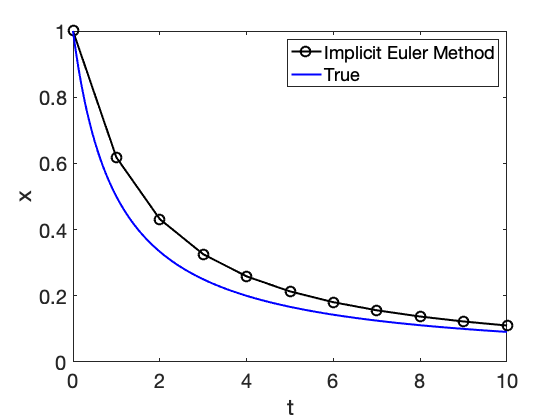

plot(tplot,truesolution(tplot),'b-','linewidth',2)
xlabel('t');
ylabel('x');
legend('Implicit Euler Method','True');
axis([0 10 0 1])

Crank-Nicholson method 

t=0:Delta_t:10;
 
%Preallocating memory
x=zeros(size(t));
 
x(1)=1;
for n=1:length(t)-1
    x(n+1)=Findxnplus1CN(Delta_t,x(n));
end

figure
plot(t,x,'ko-','linewidth',2,'Markersize',10);
axis([0 10 0.0 1.1])

hold on
 
tplot=0:0.01:10.0;
truesolution=@(t)(1./(t+1))

truesolution = function_handle with value:
    @(t)(1./(t+1))


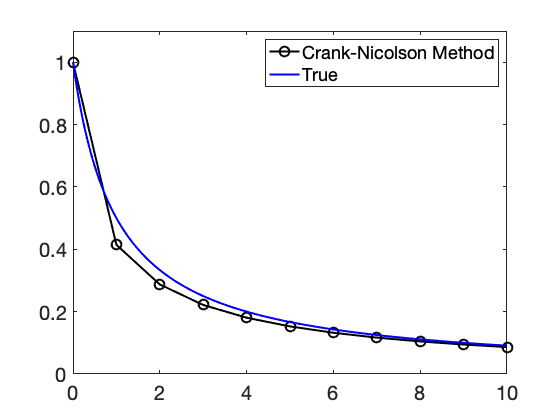

plot(tplot,truesolution(tplot),'b-','linewidth',2)
legend('Crank-Nicolson Method','True');

function p=Findxnplus1(Delta_t,xn)
%initial guess value of p
p=xn;
gp=Delta_t*p^2+p-xn;
dgdp=Delta_t*2*p+1;
 
while abs(gp)>1.0e-15
    p=p-gp/dgdp;
    gp=Delta_t*p^2+p-xn;
    dgdp=Delta_t*2*p+1;
end
end

function p=Findxnplus1CN(Delta_t,xn)
%initial guess value of p
p=xn;
gp=(Delta_t/2)*p^2+p-xn+(Delta_t/2)*xn^2;
dgdp=Delta_t*p+1;
 
while abs(gp)>1.0e-15
    p=p-gp/dgdp;
    gp=(Delta_t/2)*p^2+p-xn+(Delta_t/2)*xn^2;
    dgdp=Delta_t*p+1;
end
end